# Programming

## Flow Control

The most important programming constructs are discussed: conditional execution, repetitions and error recovery.

### Conditional Control

This section covers those MATLAB functions that provide conditional program control.

#### `if`

The `if` statement evaluates a logical expression and executes a group of statements when the expression is true. The optional `elseif` and `else` keywords provide for the execution of alternate groups of statements. An `end` keyword, which matches the `if`, terminates the last group of statements. The groups of statements are delineated by the four keywords—no braces or brackets are involved.

The MATLAB algorithm for generating a magic square of order $n$ involves three different cases: when $n^$ is odd, when $n$ is even but not divisible by 4, or when $n$ is divisible by 4. This is described by

For most values of $n$ in this example, the three cases are mutually exclusive. For values that are not mutually exclusive, such as $n=5$, the first true condition is executed.

It is important to understand how relational operators and `if` statements work with matrices. When you want to check for equality between two variables, you might use

This is valid MATLAB code, and does what you expect when `A` and `B` are scalars. But when `A` and `B` are matrices, `A == B` does not test if they are equal, it tests where they are equal; the result is another matrix of 0’s and 1’s showing element-by-element equality. (In fact, if `A` and `B` are not the same size, then `A == B` is an error.)

A = magic(4); B = A; B(1,1) = 0;
A == B

ans = 4×4 logical array
   0   1   1   1
   1   1   1   1
   1   1   1   1
   1   1   1   1


The proper way to check for equality between two variables is to use the `isequal` function:

isequal(A, B)

ans = logical
   0

`isequal` returns a scalar logical value of 1 (representing true) or 0 (false), instead of a matrix, as the expression to be evaluated by the `if` function. 

Here is another example to emphasize this point. If `A` and `B` are scalars, the following program will never reach the “unexpected situation”. But for most pairs of matrices, including our magic squares with interchanged columns, none of the matrix conditions `A > B`, `A < B`, or `A == B` is true for all elements and so the `else` clause is executed:

if A > B
    'greater'
elseif A < B
    'less'
elseif A == B
    'equal'
else
    error('Unexpected situation')
end

Unexpected situation

Several functions are helpful for reducing the results of matrix comparisons to scalar conditions for use with `if`, including `isequal`, `isempty`, `all`, and `any`.

#### `switch` and `case`

The `switch` statement executes groups of statements based on the value of a variable or expression. The keywords `case` and `otherwise` delineate the groups. Only the first matching case is executed. There must always be an `end` to match the switch.

The logic of the magic squares algorithm can also be described by

Unlike the C language `switch` statement, MATLAB switch does not fall through. If the first `case` statement is true, the other `case` statements do not execute. So, `break` statements are not required.

### Loop Control

This section covers those MATLAB functions that provide control over program loops.

#### `for`

The `for` loop repeats a group of statements a fixed, predetermined number of times. A matching `end` delineates the statements:

for n = 3:10
    r(n) = rank(magic(n));
end
r

r =      0     0     3     3     5     5     7     3     9     7


The semicolon terminating the inner statement suppresses repeated printing.

It is a good idea to indent the loops for readability, especially when they are nested:

#### `while`

The `while` loop repeats a group of statements an indefinite number of times under control of a logical condition. A matching `end` delineates the statements.

Here is a complete program, illustrating `while`, `if`, `else`, and `end`, that uses interval bisection to find a zero of a polynomial:

a = 0; fa = -Inf; b = 3;
while b-a > eps*b
    x = (a+b)/2;
    fx = x^3-2*x-5;
    if sign(fx) == sign(fa)
        a = x; 
        fa = fx;
    else
        b = x;
    end
end
x

x =      2.094551481542327e+00

The result is a root of the polynomial $x^3 - 2x - 5$.

The cautions involving matrix comparisons that are discussed in the section on the `if` statement also apply to the `while` statement.

#### `continue`

The `continue` statement passes control to the next iteration of the `for` loop or `while` loop in which it appears, skipping any remaining statements in the body of the loop. The same holds true for `continue` statements in nested loops. That is, execution continues at the beginning of the loop in which the `continue` statement was encountered.

The example below shows a `continue` loop that counts the lines of code in the file `magic.m`, skipping all blank lines and comments. A `continue` statement is used to advance to the next line in `magic.m` without incrementing the count whenever a blank line or comment line is encountered:

fid = fopen('magic.m','r'); count = 0;
while ~feof(fid)
    line = fgetl(fid);
    if isempty(line) | strncmp(line,'%',1)
        continue 
    end
    count = count + 1;
end
disp(sprintf('%d lines',count));

31 lines


#### `break`

The `break` statement lets you exit early from a `for` loop or `while` loop. In nested loops, `break` exits from the innermost loop only.

Here is an improvement on the example from the previous section. Why is this use of `break` a good idea?

a = 0; fa = -Inf; b = 3;
while b-a > eps*b
    x = (a+b)/2;
    fx = x^3-2*x-5; 
    if abs(fx) < eps
        break
    elseif sign(fx) == sign(fa)
        a = x; 
        fa = fx; 
    else
        b = x;
    end
end
x

x =      2.094551481542327e+00

### Error Control

This section covers those MATLAB functions that provide error handling control.

The general form of a `try`-`catch` statement sequence is 

In this sequence the statements between `try` and `catch` are executed until an error occurs. The statements between `catch` and `end` are then executed. Use `lasterr` to see the cause of the error. If an error occurs between `catch` and `end`, MATLAB terminates execution unless another `try` - `catch` sequence has been established.

### Program Termination

`return` terminates the current sequence of commands and returns control to the invoking function or to the keyboard. `return` is also used to terminate keyboard mode. A called function normally transfers control to the function that invoked it when it reaches the end of the function. You can insert a `return` statement within the called function to force an early termination and to transfer control to the invoking function.

## Data Structures

### Multidimensional Arrays

*Multidimensional arrays* in MATLAB are arrays with more than two subscripts. One way of creating a multidimensional array is by calling `zeros`, `ones`, `rand`, or `randn` with more than two arguments. For example,

R = randn(3,4,3)

R = R(:,:,1) =
     2.323470126244768e-01    -2.364545837571863e-01     2.229445680456899e+00    -1.664164474987060e+00
     4.263875574089450e-01     2.023690886603053e+00     3.375637006131064e-01    -5.900345642052215e-01
    -3.728087417235042e-01    -2.258353970496191e+00     1.000060819589125e+00    -2.780641637653093e-01
R(:,:,2) =
     4.227156912204783e-01    -1.212847199674459e+00     3.270599671770875e-01    -6.509077365977526e-01
    -1.670200697850470e+00     6.619004842461142e-02     1.082633504236756e+00     2.570561574339689e-01
     4.716343264163027e-01     6.523558886613740e-01     1.006077110819051e+00    -9.443778064042190e-01
R(:,:,3) =
    -1.321788521392564e+00    -5.491891460940670e-02     3.502011738745352e-01     2.397632570585800e-01
     9.248259334937059e-01     9.111272656538598e-01     1.250251228304996e+00    -6.903611031112258e-01
     4.984907525081331e-05     5.945836974090524e-01     9.297894585577157e-01    -6.515536417502810e-01

creates a 3-by-4-by-3 array with a total of 3*4*3 = 36 normally distributed random elements.

A three-dimensional array might represent three-dimensional physical data, say the temperature in a room, sampled on a rectangular grid. Or it might represent a sequence of matrices, `A(k)`, or samples of a time-dependent matrix, `A(t)`. In these latter cases, the $(i, j)$th element of the $k$th matrix is denoted by `A(i,j,k)`.

MATLAB and Dürer’s versions of the magic square of order 4 differ by an interchange of two columns. Many different magic squares can be generated by interchanging columns. The statement

p = perms(1:4);

generates the $4! = 24$ permutations of `1:4`. The $k$th permutation is the row vector `p(k,:)`. Then 

A = magic(4);
M = zeros(4,4,24);
for k = 1:24
    M(:,:,k) = A(:,p(k,:));
end

stores the sequence of 24 magic squares in a three-dimensional array, `M`. The size of `M` is

size(M)

ans =      4     4    24


The statement `sum(M,d)` computes sums by varying the $d$th subscript. So

sum(M,1)

ans = ans(:,:,1) =
    34    34    34    34
ans(:,:,2) =
    34    34    34    34
ans(:,:,3) =
    34    34    34    34
ans(:,:,4) =
    34    34    34    34
ans(:,:,5) =
    34    34    34    34
ans(:,:,6) =
    34    34    34    34
ans(:,:,7) =
    34    34    34    34
ans(:,:,8) =
    34    34    34    34
ans(:,:,9) =
    34    34    34    34
ans(:,:,10) =
    34    34    34    34
ans(:,:,11) =
    34    34    34    34
ans(:,:,12) =
    34    34    34    34
ans(:,:,13) =
    34    34    34    34
ans(:,:,14) =
    34    34    34    34
ans(:,:,15) =
    34    34    34    34
ans(:,:,16) =
    34    34    34    34
ans(:,:,17) =
    34    34    34    34
ans(:,:,18) =
    34    34    34    34
ans(:,:,19) =
    34    34    34    34
ans(:,:,20) =
    34    34    34    34
ans(:,:,21) =
    34    34    34    34
ans(:,:,22) =
    34    34    34    34
ans(:,:,23) =
    34    34    34    34
ans(:,:,24) =
    34    34    34    34

is a 1-by-4-by-24 array containing 24 copies of the row vector 


$$\pmatrix{34& 34& 34& 34}$$


and

sum(M,2)

ans = ans(:,:,1) =
    34
    34
    34
    34
ans(:,:,2) =
    34
    34
    34
    34
ans(:,:,3) =
    34
    34
    34
    34
ans(:,:,4) =
    34
    34
    34
    34
ans(:,:,5) =
    34
    34
    34
    34
ans(:,:,6) =
    34
    34
    34
    34
ans(:,:,7) =
    34
    34
    34
    34
ans(:,:,8) =
    34
    34
    34
    34
ans(:,:,9) =
    34
    34
    34
    34
ans(:,:,10) =
    34
    34
    34
    34
ans(:,:,11) =
    34
    34
    34
    34
ans(:,:,12) =
    34
    34
    34
    34
ans(:,:,13) =
    34
    34
    34
    34
ans(:,:,14) =
    34
    34
    34
    34
ans(:,:,15) =
    34
    34
    34
    34
ans(:,:,16) =
    34
    34
    34
    34
ans(:,:,17) =
    34
    34
    34
    34
ans(:,:,18) =
    34
    34
    34
    34
ans(:,:,19) =
    34
    34
    34
    34
ans(:,:,20) =
    34
    34
    34
    34
ans(:,:,21) =
    34
    34
    34
    34
ans(:,:,22) =
    34
    34
    34
    34
ans(:,:,23) =
    34
    34
    34
    34
ans(:,:,24) =
    34
    34
    34
  

is a 4-by-1-by-24 array containing 24 copies of the column vector


$$\pmatrix{34 \cr34 \cr34 \cr34}$$


Finally,

sum(M,3)

ans =    204   204   204   204
   204   204   204   204
   204   204   204   204
   204   204   204   204


adds the 24 matrices in the sequence. The result has size 4-by-4-by-1, so it looks like a 4-by-4 array.

### Cell Arrays

*Cell arrays* in MATLAB are multidimensional arrays whose elements are copies of other arrays. A cell array of empty matrices can be created with the cell function. But, more often, cell arrays are created by enclosing a miscellaneous collection of things in curly braces, `{}`. The curly braces are also used with subscripts to access the contents of various cells. For example,

C = {A sum(A) prod(prod(A))}

C = 1×3 cell array
    {4×4 double}    {1×4 double}    {[2.0923e+13]}


produces a 1-by-3 cell array. The three cells contain the magic square, the row vector of column sums, and the product of all its elements.

The first cell is too large to print in this limited space.

Here are two important points to remember. First, to retrieve the contents of one of the cells, use subscripts in curly braces. For example, `C{1}` retrieves the magic square and `C{3}` is $16!$. Second, cell arrays contain copies of other arrays, not pointers to those arrays. If you subsequently change `A`, nothing happens to `C`.

You can use three-dimensional arrays to store a sequence of matrices of the same size. Cell arrays can be used to store a sequence of matrices of different sizes. For example,

M = cell(8,1);
for n = 1:8
    M{n} = magic(n);
end
M

M = 8×1 cell array
    {[       1]}
    {2×2 double}
    {3×3 double}
    {4×4 double}
    {5×5 double}
    {6×6 double}
    {7×7 double}
    {8×8 double}


produces a sequence of magic squares of different order.

You can retrieve the 4-by-4 magic square matrix with

M{4}

ans =     16     2     3    13
     5    11    10     8
     9     7     6    12
     4    14    15     1


### Characters and Text

Enter text into MATLAB using single quotes. For example,

s = 'Hello'

s = 'Hello'

The result is not the same kind of numeric matrix or array you have been dealing with up to now. It is a 1-by-5 *character array*.

Internally, the characters are stored as numbers, but not in floating-point format. The statement

a = double(s)

a =     72   101   108   108   111


converts the character array to a numeric matrix containing floating-point representations of the *ASCII codes* for each character. 

The statement

s = char(a)

s = 'Hello'

reverses the conversion.

Converting numbers to characters makes it possible to investigate the various fonts available on your computer. The printable characters in the basic ASCII character set are represented by the integers `32:127`. (The integers less than 32 represent nonprintable control characters.) These integers are arranged in an appropriate 6-by-16 array with

F = reshape(32:127,16,6)';

The printable characters in the extended ASCII character set are represented by `F+128`. When these integers are interpreted as characters, the result depends on the font currently being used. Type the statements

char(F)

ans = 6×16 char array
    ' !"#$%&'()*+,-./'
    '0123456789:;<=>?'
    '@ABCDEFGHIJKLMNO'
    'PQRSTUVWXYZ[\]^_'
    '`abcdefghijklmno'
    'pqrstuvwxyz{|}~'


char(F+128)

ans = 6×16 char array
    ' ¡¢£¤¥¦§¨©ª«¬­®¯'
    '°±²³´µ¶·¸¹º»¼½¾¿'
    'ÀÁÂÃÄÅÆÇÈÉÊËÌÍÎÏ'
    'ÐÑÒÓÔÕÖ×ØÙÚÛÜÝÞß'
    'àáâãäåæçèéêëìíîï'
    'ðñòóôõö÷øùúûüýþÿ'


Concatenation with square brackets joins text variables together into larger strings. The statement

h = [s, ' world']

h = 'Hello world'

joins the strings horizontally.

The statement

v = [s; 'world']

v = 2×5 char array
    'Hello'
    'world'


creates a char array with multiple rows.

Note that both words in `v` have to have the same length. The resulting arrays are both character arrays; `h` is 1-by-11 and `v` is 2-by-5.

To manipulate a body of text containing lines of different lengths, you have two choices—a padded character array or a cell array of strings. When creating a character array, you must make each row of the array the same length. (Pad the ends of the shorter rows with spaces.) The `char` function does this padding for you. For example,

S = char('A','rolling','stone','gathers','momentum.')

S = 5×9 char array
    'A        '
    'rolling  '
    'stone    '
    'gathers  '
    'momentum.'


Alternatively, you can store the text in a cell array. For example,

C = {'A';'rolling';'stone';'gathers';'momentum.'}

C = 5×1 cell array
    {'A'        }
    {'rolling'  }
    {'stone'    }
    {'gathers'  }
    {'momentum.'}


creates a 5-by-1 cell array that requires no padding because each row of the array can have a different length.

You can convert a padded character array to a cell array of strings with

C = cellstr(S)

C = 5×1 cell array
    {'A'        }
    {'rolling'  }
    {'stone'    }
    {'gathers'  }
    {'momentum.'}


and reverse the process with

S = char(C)

S = 5×9 char array
    'A        '
    'rolling  '
    'stone    '
    'gathers  '
    'momentum.'


### Structures

`Structures` are multidimensional MATLAB arrays with elements accessed by textual field designators. For example,

clear S
S.name = 'Ed Plum'; S.score = 83; S.grade = 'B+'

S = struct with fields:
     name: 'Ed Plum'
    score: 83
    grade: 'B+'


creates a scalar structure with three fields.

Like everything else in MATLAB, structures are arrays, so you can insert additional elements. In this case, each element of the array is a structure with several fields. The fields can be added one at a time,

S(2).name = 'Toni Miller'; S(2).score = 91; S(2).grade = 'A-';

or an entire element can be added with a single statement:

S(3) = struct('name','Jerry Garcia','score',70,'grade','C')

S = 1×3 struct array with fields:
    name
    score
    grade


There are several ways to reassemble the various fields into other MATLAB arrays. They are mostly based on the notation of a comma-separated list. If you type

S.score

ans = 83

ans = 91

ans = 70

it is the same as typing

S(1).score, S(2).score, S(3).score

ans = 83

ans = 91

ans = 70

which is a comma-separated list.

If you enclose the expression that generates such a list within square brackets, MATLAB stores each item from the list in an array. In this example, MATLAB creates a numeric row vector containing the score field of each element of structure array `S`:

scores = [S.score]

scores =     83    91    70


avg_score = sum(scores)/length(scores)

avg_score = 81.3333

To create a character array from one of the text fields (`name`, for example), call the `char` function on the comma-separated list produced by `S.name`:

names = char(S.name)

names = 3×12 char array
    'Ed Plum     '
    'Toni Miller '
    'Jerry Garcia'


## Scripts and Functions

MATLAB is a powerful programming language as well as an interactive computational environment. Files that contain code in the MATLAB language are called *M-files*. You create M-files using a text editor, then use them as you would any other MATLAB function or command.

There are two kinds of M-files:

- *Scripts*, which do not accept input arguments or return output arguments. They operate on data in the workspace.

- *Functions*, which can accept input arguments and return output arguments. Internal variables are local to the function.

If you’re a new MATLAB programmer, just create the M-files that you want to try out in the current directory. As you develop more of your own M-files, you will want to organize them into other directories and personal toolboxes that you can add to your MATLAB search path.

If you duplicate function names, MATLAB executes the one that occurs first in the search path.

To view the contents of an M-file, for example, `myfunction.m`, use `type myfunction`.

### Scripts

When you invoke a script, MATLAB simply executes the commands found in the file. Scripts can operate on existing data in the workspace, or they can create new data on which to operate. Although scripts do not return output arguments, any variables that they create remain in the workspace, to be used in subsequent computations. In addition, scripts can produce graphical output using functions like plot.

For example, create a file called `magicrank.m` that contains these MATLAB commands:

Typing the statement

r =      0     0     3     3     5     5     7     3     9     7    11     3    13     9    15     3    17    11    19     3    21    13    23     3    25    15    27     3    29    17    31     3


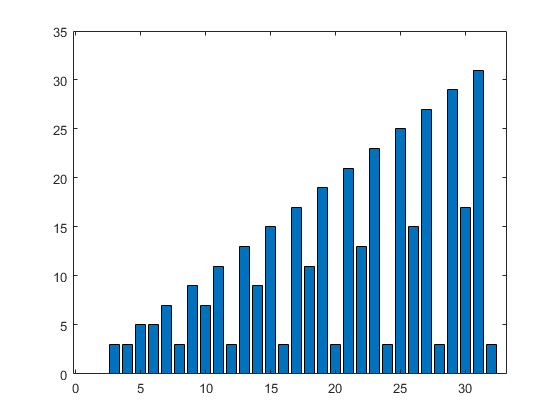

magicrank

causes MATLAB to execute the commands, compute the rank of the first 30 magic squares, and plot a bar graph of the result. After execution of the file is complete, the variables `n` and `r` remain in the workspace.

### Functions

Functions are M-files that can accept input arguments and return output arguments. The names of the M-file and of the function should be the same. Functions operate on variables within their own workspace, separate from the workspace you access at the MATLAB command prompt.

A good example is provided by rank. The M-file `rank.m` is available in the directory `toolbox/matlab/matfun`. You can see the file with `type rank`

The first line of a function M-file starts with the keyword function. It gives the function name and order of arguments. In this case, there are up to two input arguments and one output argument.

The next several lines, up to the first blank or executable line, are comment lines that provide the help text. These lines are printed when you type

help rank

 rank   Matrix rank.
    rank(A) provides an estimate of the number of linearly
    independent rows or columns of a matrix A.
 
    rank(A,TOL) is the number of singular values of A
    that are larger than TOL. By default, TOL = max(size(A)) * eps(norm(A)).
 
    Class support for input A:
       float: double, single

    Documentation for rank
    Other functions named rank



The first line of the help text is the `H1` line, which MATLAB displays when you use the `lookfor` command or request help on a directory.

The rest of the file is the executable MATLAB code defining the function. The variable `s` introduced in the body of the function, as well as the variables on the first line, `r`, `A` and `tol`, are all local to the function; they are separate from any variables in the MATLAB workspace.

This example illustrates one aspect of MATLAB functions that is not ordinarily found in other programming languages—a variable number of arguments. The rank function can be used in several different ways:

rank(A)

ans = 3

rank(A,1.e-6)

ans = 3

r =

     3

Many M-files work this way. If no output argument is supplied, the result is stored in `ans`. If the second input argument is not supplied, the function computes a default value. Within the body of the function, two quantities named `nargin` and `nargout` are available that tell you the number of input and output arguments involved in each particular use of the function. The `rank` function uses `nargin`, but does not need to use `nargout`.

#### Anonymous Functions

An `anonymous function` is a simple form of MATLAB function that does not require an M-file. It consists of a single MATLAB expression and any number of input and output arguments. You can define an anonymous function right at the MATLAB command line, or within an M-file function or script. This gives you a quick means of creating simple functions without having to create M-files each time.

The syntax for creating an anonymous function from an expression is `f = @(arglist)expression`.

The statement below creates an anonymous function that finds the square of a number. When you call this function, MATLAB assigns the value you pass in to variable `x`, and then uses `x` in the equation `x.^2`:

sqr = @(x) x.^2;
a = sqr(5)

a = 25

#### Primary and Subfunctions

All functions that are not anonymous must be defined within an M-file. Each M-file has a required *primary function* that appears first in the file, and any number of *subfunctions* that follow the primary. Primary functions have a wider scope than subfunctions. That is, primary functions can be invoked from outside of their M-file (from the MATLAB command line or from functions in other M-files) while subfunctions cannot. Subfunctions are visible only to the primary function and other subfunctions within their own M-file.

#### Function Overloading

Overloaded functions act the same way as overloaded functions in most computer languages. Overloaded functions are useful when you need to create a function that responds to different types of inputs accordingly. For instance, you might want one of your functions to accept both double-precision and integer input, but to handle each type somewhat differently. You can make this difference invisible to the user by creating two separate functions having the same name, and designating one to handle double types and one to handle integers. When you call the function, MATLAB chooses which M-file to dispatch to based on the type of the input arguments. 

#### Global Variables

If you want more than one function to share a single copy of a variable, simply declare the variable as `global` in all the functions. Do the same thing at the command line if you want the base workspace to access the variable.

The global declaration must occur before the variable is actually used in a function. Although it is not required, using capital letters for the names of global variables helps distinguish them from other variables. For example, create an M-file called `falling.m`:

Then interactively enter the statements

global GRAVITY
GRAVITY = 32;
y = falling((0:.1:5)')

y =          0
    0.1600
    0.6400
    1.4400
    2.5600
    4.0000
    5.7600
    7.8400
   10.2400
   12.9600


The two global statements make the value assigned to `GRAVITY` at the command prompt available inside the function. You can then modify `GRAVITY` interactively and obtain new solutions without editing any files.

#### The `eval` Function

The `eval` function works with text variables to implement a powerful text macro facility. The expression or statement `eval(s)` uses the MATLAB interpreter to evaluate the expression or execute the statement contained in the text string `s`.

for d = 1:31
    s = ['disp("January ' int2str(d) '")']; 
    eval(s)
end

January 1
January 2
January 3
January 4
January 5
January 6
January 7
January 8
January 9
January 10
January 11
January 12
January 13
January 14
January 15
January 16
January 17
January 18
January 19
January 20
January 21
January 22
January 23
January 24
January 25
January 26
January 27
January 28
January 29
January 30
January 31


#### Function Handles

You can create a *handle* to any MATLAB function and then use that handle as a means of referencing the function. A function handle is typically passed in an argument list to other functions, which can then execute, or evaluate, the function using the handle.

Construct a function handle in MATLAB using the at sign, `@`, before the function name. The following example creates a function handle for the `sin` function and assigns it to the variable `fhandle`:

fhandle = @sin;

You can call a function by means of its handle in the same way that you would call the function using its name. The syntax is `fhandle(arg1, arg2, ...);`

The function `plot_fhandle`, shown below, receives a function handle and data, generates y-axis data using the function handle, and plots it:

When you call `plot_fhandle` with a handle to the `sin` function and the argument shown below, the resulting evaluation produces a sine wave plot:

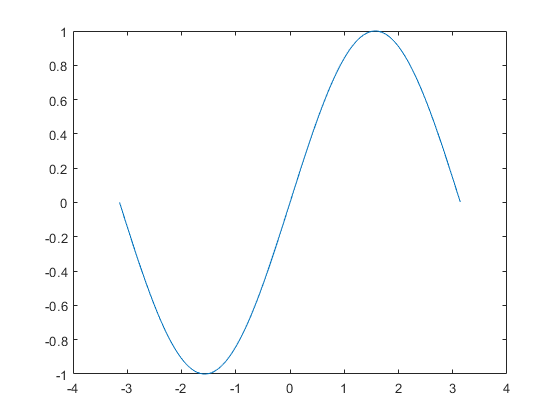

plot_fhandle(@sin, -pi:0.01:pi)

#### Function Functions

A class of functions called *function functions* works with nonlinear functions of a scalar variable. That is, one function works on another function. The function functions include

- Zero finding

- Optimization

- Quadrature

MATLAB represents the nonlinear function by a function M-file. For example, here is a simplified version of the function humps from the matlab/demos directory:

Evaluate this function at a set of points in the interval $0 \le x \le 1$ with

x = 0:.002:1;
y = humps(x);

Then plot the function with

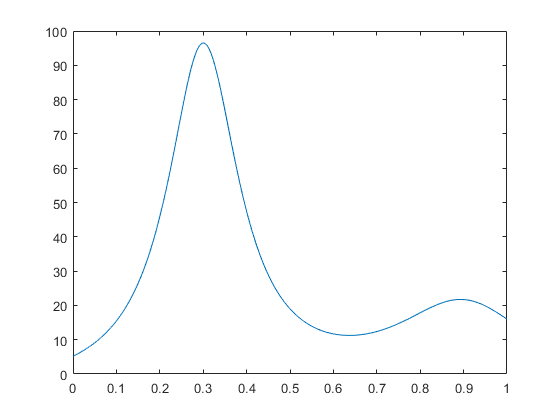

plot(x,y)

The graph shows that the function has a local minimum near $x = 0.6$. The function `fminsearch` finds the minimizer, the value of `x` where the function takes on this minimum. The first argument to `fminsearch` is a function handle to the function being minimized and the second argument is a rough guess at the location of the minimum:

p = fminsearch(@humps,.5)

p = 0.6370

To evaluate the function at the minimizer,

humps(p)

ans = 11.2528

Numerical analysts use the terms quadrature and integration to distinguish between numerical approximation of definite integrals and numerical integration of ordinary differential equations. MATLAB quadrature routines are `quad` and `quadl`. The statement

Q = quadl(@humps,0,1)

Q = 29.8583

computes the area under the curve in the graph.

Finally, the graph shows that the function is never zero on this interval. So, if you search for a zero with

z = fzero(@humps,.5)

z = -0.1316

you will find one outside the interval.

## Performance

### Vectorization

One way to make your MATLAB programs run faster is to vectorize the algorithms you use in constructing the programs. Where other programming languages might use `for` loops loops, MATLAB can use vector or matrix operations. A simple example involves creating a table of logarithms:

x = .01;
for k = 1:1001
    y(k) = log10(x);
    x = x + .01; 
end

A vectorized version of the same code is

x = .01:.01:10; y = log10(x);

For more complicated code, vectorization options are not always so obvious.

### Preallocation

If you cannot vectorize a piece of code, you can make your `for` loops go faster by preallocating any vectors or arrays in which output results are stored. For example, this code uses the function zeros to preallocate the vector created in the `for` loop. This makes the for loop execute significantly faster:

r = zeros(32,1);
for n = 1:32
    r(n) = rank(magic(n));
end

Without the preallocation in the previous example, the MATLAB interpreter enlarges the `r` vector by one element each time through the loop. Vector preallocation eliminates this step and results in faster execution.